clear all
clc;

## Radar Specifications

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%speed of light = 3e8

## User Defined Range and Velocity of target

initial_target_range=110;%initial range position
v_init= 20; %(m/s) vehicle initial velocity

## FMCW Waveform Generation

%Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.
c= 3*10^8;
rangeResolution= 1;
B= c/2*rangeResolution;
RangeMax= 200;
Tchirp=5.5*2*RangeMax/c;
Slope=B/Tchirp;


%Operating carrier frequency of Radar 
fc= 77e9;             %carrier freq
T= 1/fc;
                                                          
%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


## Signal generation and Moving Target simulation

Running the radar scenario over the time. 

%Range of the Target for constant velocity
rt= t.*v_init + initial_target_range;
td= rt*(2/c);
%update the transmitted and received signal
Tx= cos(2*pi.*(fc.*t + Slope*t.*t/2));
Rx= cos(2*pi.*(fc.*(t-td) + Slope.*(t-td).*(t-td)/2));
Mix= Tx.*Rx; %difference signal


## RANGE MEASUREMENT

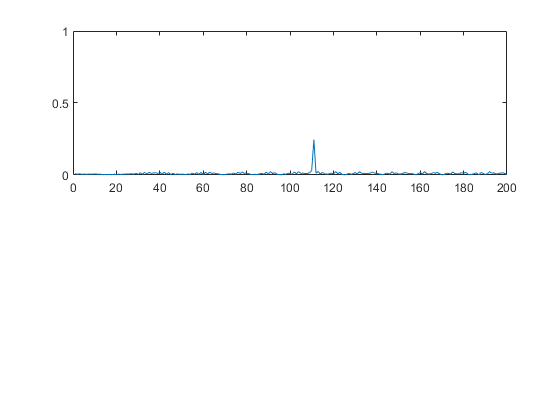

%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
Beat= reshape(Mix, [Nr, Nd]);
%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.
MixFFT=fft(Beat)./Nr;
% Take the absolute value of FFT output
BeatFFTAbs= abs(MixFFT);
% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
BeatFFTAbsSSide= BeatFFTAbs(1:length(BeatFFTAbs)/2-1);

%plotting the range
figure ('Name','Range from First FFT')
subplot(2,1,1)

 % plot FFT output 
 
 plot(BeatFFTAbsSSide);
 
 axis ([0 200 0 1]);

## RANGE DOPPLER RESPONSE

The 2D FFT implementation is already provided here. This will run a 2DFFT on the mixed signal (beat signal) output and generate a range doppler map.You will implement CFAR on the generated RDM

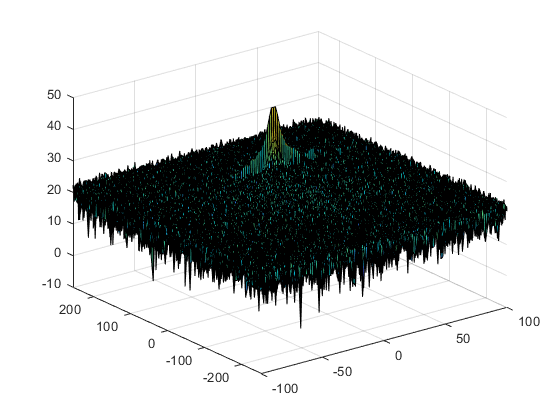

% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

## CFAR implementation

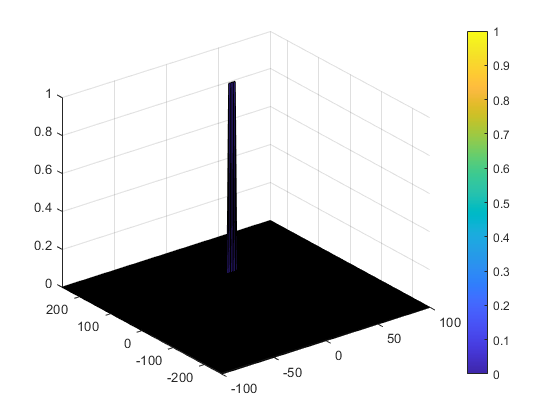

%Slide Window through the complete Range Doppler Map

%Select the number of Training Cells in both the dimensions.
train_r = 8;
train_d = 4;  

%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation
guard_r = 8;
guard_d = 4;

cut_r = 1;
cut_d = 1;

% offset the threshold by SNR value in dB
offset = log(5);

%Create area containing the guard , cut and training cells
conv_kern_center = ones([guard_r+cut_r+ train_r, guard_d+cut_d+train_d]); 

%Fill the kernel area with guard and cut cells with zeros
conv_kern_center(train_r:end-train_r+1,train_d:end-train_d+1) =0; 

%Normalize the kernel of training , guard and cut kernel
conv_kern_center = conv_kern_center/sum(conv_kern_center, 'all');

%Compute thresholds by using convolution between Train+Cut+Guard with
%SIgnal
edge_pad_size = 0.5*(-size(offset*conv2(RDM,conv_kern_center,'valid'))+size(RDM));
thresholds = padarray(offset*conv2(RDM,conv_kern_center,'valid'), edge_pad_size, NaN(1), 'both');

%check threhsold to filter signal
cfar= (RDM>thresholds).*1;

%display the CFAR output using the Surf function like we did for Range
%Doppler Response output.
figure,surf(doppler_axis,range_axis,cfar);
colorbar;